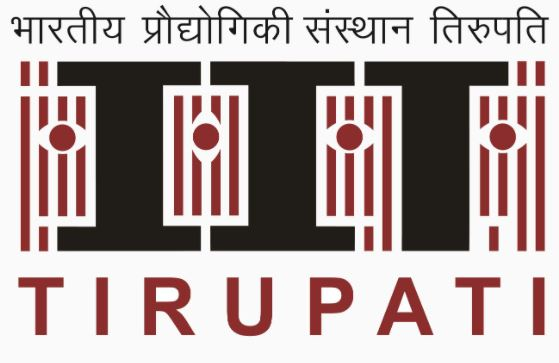

### **Digital Signal Processing Laboratory**

**LabSheet-03**

Name: Suriyaa MM

Roll Number: EE23B054

#### A. Observation of Gibbs Phenomenon

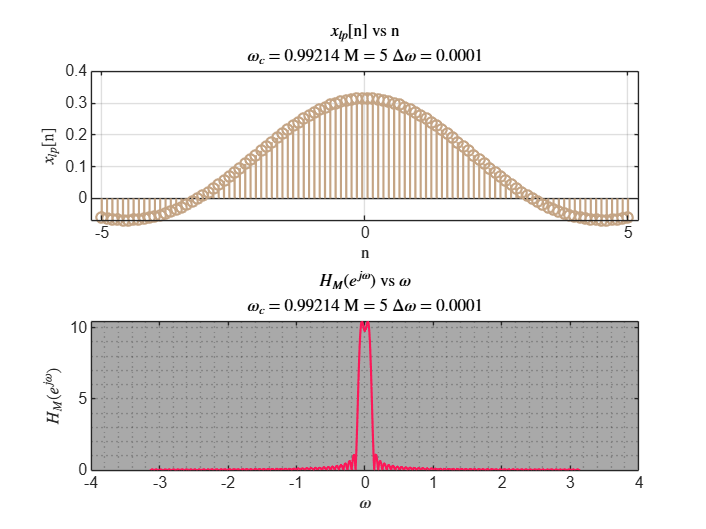

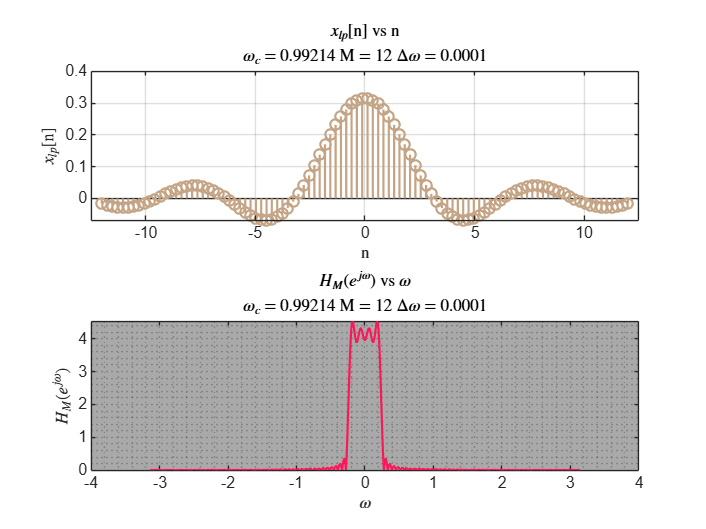

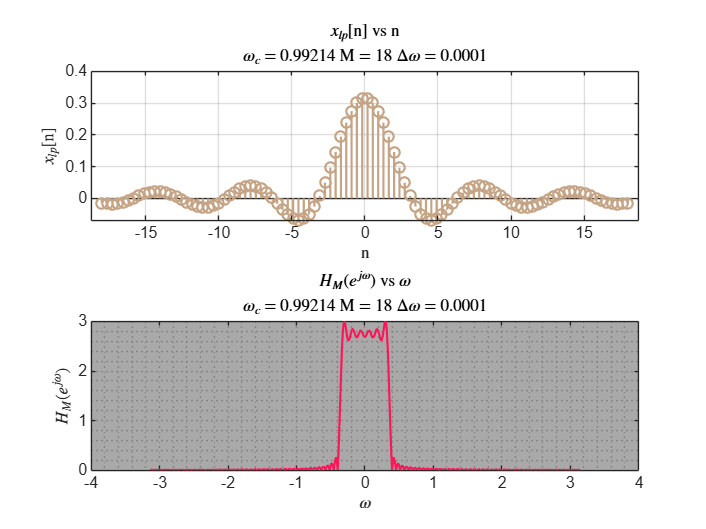

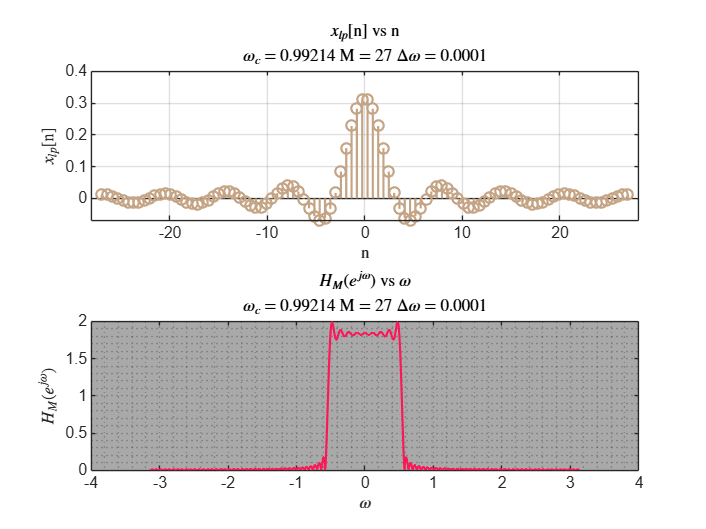

COLOUR_BROWN    = "#c4a484";
COLOUR_RED      = "#fc1758";
COLOUR_BLUE     = "#4a8af0";
COLOUR_GREY     = "#A9A9A9";

% Fix a value of w_c
w_c = pi * rand();

for M = [5 12 18 27]

    % Generate n as a Linear Array of size 100
    n = linspace(-M, M, 100);

    hlp = zeros(size(n));

    % Compute hlp[n]
    for idx = 1:length(n)
        % If n != 0
        if n(idx) ~= 0
            hlp(idx) = sin(w_c * n(idx)) / (pi * n(idx));
        else
            hlp(idx) = w_c / pi; 
        end
    end

    % Define the frequency range for w
    deltaw = 0.0001;
    w = -pi:deltaw:pi;

    % Compute the Fourier Transform Hm(e^jw) of hlp
    Hm = fftshift(fft(hlp, length(w)));

    figure;
    figProps = gcf;
    figProps.Position(3:4) = figProps.Position(3:4) * 3;

    % Plot hlp
    subplot(2,1,1);
    stem(n, hlp, Color = COLOUR_BROWN, LineWidth = 1.25);
    xlabel('n', Interpreter = "latex");
    ylabel('$x_{lp}$[n]', Interpreter = "latex");
    title('$x_{lp}$[n] vs n', Interpreter = "latex");
    subtitle(['$\omega _c$ = ' num2str(w_c) ' M = ' num2str(M) ' $\Delta \omega$ = ' num2str(deltaw)], Interpreter = "latex");
    grid on;

    % Plot Fourier Transform of hlp
    subplot(2,1,2);
    plot(w, abs(Hm), Color = COLOUR_RED, LineWidth=1.25);
    xlabel('$\omega$', Interpreter = "latex");
    ylabel('$H_{M}(e ^ {j \omega })$', Interpreter = "latex");
    title('$H_{M}(e ^ {j \omega })$ vs $\omega$', Interpreter = "latex");
    subtitle(['$\omega _c$ = ' num2str(w_c) ' M = ' num2str(M) ' $\Delta \omega$ = ' num2str(deltaw)], Interpreter = "latex");

    set(gca, "XMinorGrid", "on");
    set(gca, "YMinorGrid", "on");
    set(gca, "Color", "#A9A9A9");

end

**Gibbs phenomenon**

- Occurs when approximating a discontinuous function using a finite number of Fourier series terms.

- The oscillations near the cutoff frequency are due to the truncation of the ideal sinc function. These oscillations do not diminish with increasing `M` but instead approach a fixed percentage of the discontinuity height.

**In Plot **$$H_{M}(e ^ {j \omega})$ vs $\omega$$ 

- The magnitude of the Fourier Transform $$H_{M}(e ^ {j \omega})$ should show a low-pass characteristic, with high values at low frequencies and attenuated values at high frequencies.

#### B. Generation of Random Sinusoid

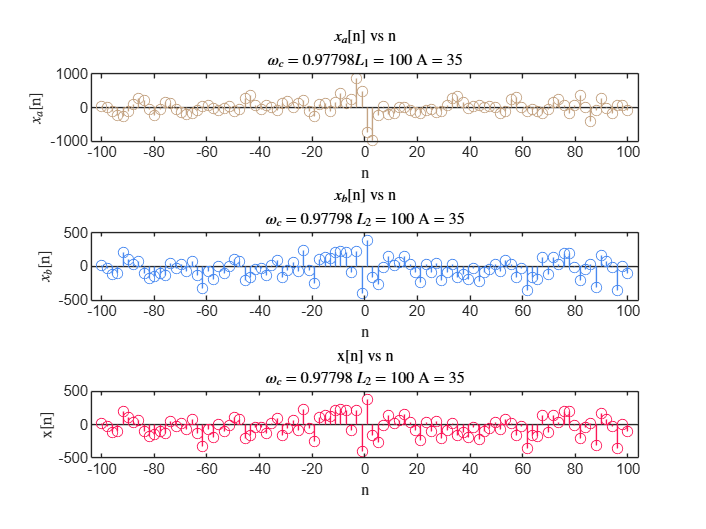

% Fix a value of w_c
w_c = pi * rand();
% Fix a value of L1
L1 = 100;
% Fix a value of A between 1 and 100
A = randi(100);
% Fix a value of N between 1 and 100 and generate n <= N
N = 100;
n = linspace(-N, N, L1);

% Generation of discerete w in range [0, w_c] which is an Linear array of size L1
w = w_c * rand(1, L1);

% Generation of discerte A in range [1, A] which is a Linear array of size L1
a = 1 + A * rand(1, L1);

% Generation of discrete phi in range [-pi, pi] which is a Linear array of size L1
phi = 2*pi + pi * rand(1, L1);

% Initialize the signal x_a[n]
x_a = zeros(size(n));

% Construct the signal
for i = 1:L1
    x_a = x_a + a(i) * cos(w(i) * n + phi(i)); % Summing the contributions
end

figure;
figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 3;

subplot(3,1,1);
stem(n, x_a, Color = COLOUR_BROWN);
xlabel('n', Interpreter = "latex");
ylabel('$x_a$[n]', Interpreter = "latex");
title('$x_a$[n] vs n', Interpreter = "latex");
subtitle(['$\omega _c$ = ' num2str(w_c) '$L_1$ = ' num2str(L1) ' A = ' num2str(A)], Interpreter = "latex");

% Fix a value of L2
L2 = 100;
% generate n <= N
n = linspace(-N, N, L2);

% Generation of discerete w in range [w_c, pi] which is an Linear array of size L2
w = (pi - w_c) + pi * rand(1, L1);

% Generation of discerte A in range [1, A] which is a Linear array of size L1
a = 1 + A * rand(1, L2);

% Generation of discrete phi in range [-pi, pi] which is a Linear array of size L1
phi = 2*pi + pi * rand(1, L2);

% Initialize the signal x_a[n]
x_b = zeros(size(n));

% Construct the signal
for i = 1:L2
    x_b = x_b + a(i) * cos(w(i) * n + phi(i)); % Summing the contributions
end

subplot(3,1,2);
stem(n, x_b, Color = COLOUR_BLUE);
xlabel('n', Interpreter = "latex");
ylabel('$x_b$[n]', Interpreter = "latex");
title('$x_b$[n] vs n', Interpreter = "latex");
subtitle(['$\omega _c$ = ' num2str(w_c) ' $L_2$ = ' num2str(L2) ' A = ' num2str(A)], Interpreter = "latex");


x_n = x_a + x_b;
subplot(3,1,3);
stem(n, x_b, Color = COLOUR_RED);
xlabel('n', Interpreter = "latex");
ylabel('x[n]', Interpreter = "latex");
title('x[n] vs n', Interpreter = "latex");
subtitle(['$\omega _c$ = ' num2str(w_c) ' $L_2$ = ' num2str(L2) ' A = ' num2str(A)], Interpreter = "latex");

#### C. Filling x[n] using Truncated LPF

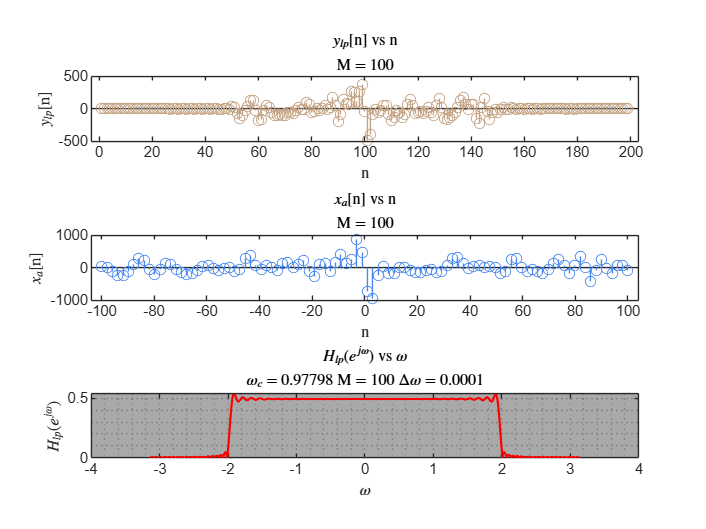

% Fix a value of M
M = 100;

% Generate n as a Linear Array of size 100
n = linspace(-M, M, 100);

hlp = zeros(size(n));

% Compute hlp[n]
for idx = 1:length(n)
    % If n != 0
    if n(idx) ~= 0
        hlp(idx) = sin(w_c * n(idx)) / (pi * n(idx));
    else
        hlp(idx) = w_c / pi; 
    end
end

% Computation of ylp
ylp = conv(x_n, hlp);

figure;
figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 3;

% Plot ylp
subplot(3,1,1);
stem(ylp, Color = COLOUR_BROWN);
xlabel('n', Interpreter = "latex");
ylabel('$y_{lp}$[n]', Interpreter = "latex");
title('$y_{lp}$[n] vs n', Interpreter = "latex");
subtitle(['M = ' num2str(M)], Interpreter = "latex");

% Plot xa
subplot(3,1,2);
stem(n, x_a, Color = COLOUR_BLUE);
xlabel('n', Interpreter = "latex");
ylabel('$x_{a}$[n]', Interpreter = "latex");
title('$x_{a}$[n] vs n', Interpreter = "latex");
subtitle(['M = ' num2str(M)], Interpreter = "latex");

% Define the frequency range for w
deltaw = 0.0001;
w = -pi:deltaw:pi;

% Compute the Fourier Transform Hm(e^jw) of hlp
Hm = fftshift(fft(hlp, length(w)));

% Plot Fourier Transform of ylp
subplot(3,1,3);
plot(w, abs(Hm), 'Color', 'red', LineWidth = 1.25);
xlabel('$\omega$', 'Interpreter', 'latex');
ylabel('$H_{lp}(e ^ {j \omega })$', 'Interpreter', 'latex');
title('$H_{lp}(e ^ {j \omega })$ vs $\omega$', 'Interpreter', 'latex');
subtitle(['$\omega _c$ = ' num2str(w_c) ' M = ' num2str(M) ' $\Delta \omega$ = ' num2str(deltaw)], 'Interpreter', 'latex');
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");
set(gca, "Color", "#A9A9A9");

In Plot $$H_{lp}(e ^ {j \omega})$ vs $\omega$$

- **Filtered Signal**: The low-pass filter effectively smooths the original signal, reducing high-frequency noise and fluctuations.

- **Original Signal**: The original signal is a complex sinusoidal signal with high-frequency components.

- **Low-Pass Filter**: The filter is designed using the sinc function, which is ideal for passing low frequencies and attenuating high frequencies.

- **Frequency Response**: The Fourier Transform of the filter shows a low-pass characteristic, with high values at low frequencies and attenuated values at high frequencies. The Gibbs phenomenon is observed as oscillations near the cutoff frequency

#### D. Filling x[n] using Moving Average System

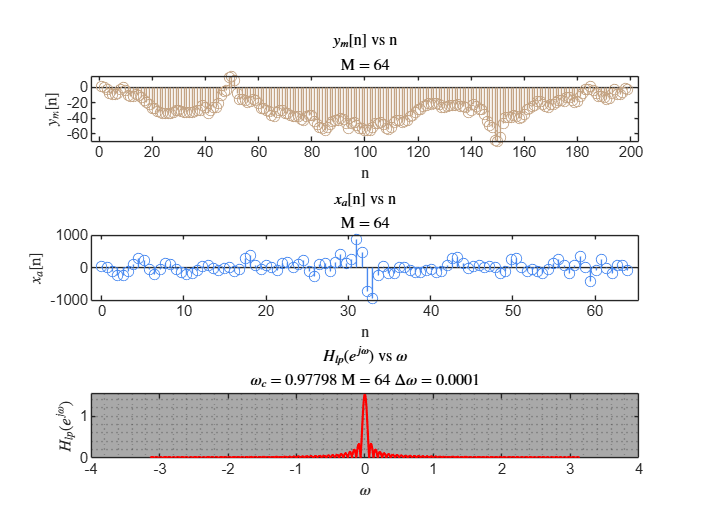

% Fix a value of M
M = 64;

% Generate n as a Linear Array of size 100
n = linspace(0, M, 100);

hm = zeros(size(n));

% Compute hlp[n]
for idx = 1:length(n)
    hm(idx) = 1/(M + 1);
end

% Compute ym
ym = conv(x_n, hm);

figure;
figProps = gcf;
figProps.Position(3:4) = figProps.Position(3:4) * 3;

subplot(3,1,1);
stem(ym, Color = COLOUR_BROWN);
xlabel('n', Interpreter = "latex");
ylabel('$y_{m}$[n]', Interpreter = "latex");
title('$y_{m}$[n] vs n', Interpreter = "latex");
subtitle(['M = ' num2str(M)], Interpreter = "latex");

subplot(3,1,2);
stem(n, x_a, Color = COLOUR_BLUE);
xlabel('n', Interpreter = "latex");
ylabel('$x_{a}$[n]', Interpreter = "latex");
title('$x_{a}$[n] vs n', Interpreter = "latex");
subtitle(['M = ' num2str(M)], Interpreter = "latex");

% Define the frequency range for w
deltaw = 0.0001;
w = -pi:deltaw:pi;

% Compute the Fourier Transform Hm(e^jw) of hlp
Hm = fftshift(fft(hm, length(w)));

% Plot Fourier Transform of ylp
subplot(3,1,3);
plot(w, abs(Hm), 'Color', 'red', LineWidth = 1.25);
xlabel('$\omega$', 'Interpreter', 'latex');
ylabel('$H_{lp}(e ^ {j \omega })$', 'Interpreter', 'latex');
title('$H_{lp}(e ^ {j \omega })$ vs $\omega$', 'Interpreter', 'latex');
subtitle(['$\omega _c$ = ' num2str(w_c) ' M = ' num2str(M) ' $\Delta \omega$ = ' num2str(deltaw)], 'Interpreter', 'latex');
set(gca, "XMinorGrid", "on");
set(gca, "YMinorGrid", "on");
set(gca, "Color", "#A9A9A9");

In Plot $$H_{lp}(e ^ {j \omega})$ vs $\omega$$

- **Filtered Signal**: The moving average filter effectively smooths the original signal, reducing high-frequency noise and fluctuations.

- **Original Signal**: The original signal is a complex sinusoidal signal with high-frequency components.

- **Moving Average Filter**: The filter is a simple low-pass filter with equal weights, designed to average the input signal over a window of size `M + 1`.

- **Frequency Response**: The Fourier Transform of the filtered signal shows a low-pass characteristic, with high values at low frequencies and attenuated values at high frequencies. The Gibbs phenomenon is observed as oscillations near the cutoff frequency.